Initiate

close all
clearvars
clc
cd ../results/

Load data files

load('dxyz.dat',             '-ascii');
load('Nxyz.dat',             '-ascii');
rho.data = load('rhoAmb.dat','-ascii');
gnd.alt  = load('z_gnd.dat', '-ascii');

Derive main parameters

N.x = Nxyz(1);
N.y = Nxyz(2);
N.z = Nxyz(3);

d.x = dxyz(1);           % _m
d.y = dxyz(2);           % _m
d.z = dxyz(3);           % _m

L.x = (N.x-1)*d.x;         % _m
L.y = (N.y-1)*d.y;         % _m
L.z = (N.z-1)*d.z;         % _m

rho.data = ConvertTo3d(rho.data,Nxyz); % _C/_m^3

clear Nxyz
clear dxyz
clear InitPoint


x = ((0:(N.x-1))*d.x)*1e-3;
y = ((0:(N.y-1))*d.y)*1e-3;
z = ((0:(N.z-1))*d.z + gnd.alt)*1e-3;

[X,Y,Z]=meshgrid(x,y,z);
rho.max = .1* max(max(max(rho.data)));
rho.min = .1* min(min(min(rho.data)));

Map ColorScale

gnd.color = [.75 .75 .75];%[.718 .255 .055];

Draw the tree

figure(1);

hold

Current plot held


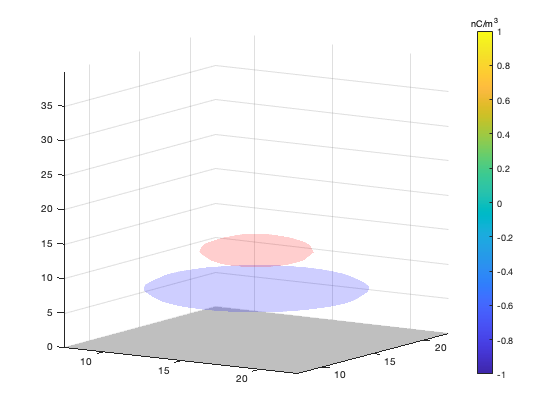


P.x = [L.x 0 0 L.x]*1e-3;
P.y = [L.y L.y 0 0]*1e-3;
P.z = [gnd.alt gnd.alt gnd.alt gnd.alt]*1e-3;
patch(P.x, P.y, P.z, gnd.alt,'FaceColor',gnd.color);

p1 = patch(isosurface(X,Y,Z,rho.data,rho.max));
isonormals(x,y,z,rho.data,p1);
set(p1,'FaceColor','red','EdgeColor','none','FaceAlpha',0.1); % set the color, mesh and transparency level of the surface


p2 = patch(isosurface(x,y,z,rho.data,rho.min));
isonormals(x,y,z,rho.data,p2);
set(p2,'FaceColor','blue','EdgeColor','none','FaceAlpha',0.1);
view([33 10])

% camlight; lighting gouraud
axis([L.x*1/4 L.x*3/4 L.y*1/4 L.y*3/4 gnd.alt 2/2*(L.z+gnd.alt)]*1e-3)
colorbar

view([33 10])
ax = gca;
ax.Colorbar.Title.String = "nC/m^3";
ax.Color;
grid on

Go back to initial folder

cd ../viz

function [AA] = ConvertTo3d(A,B)
[M, N] = size(A);
AA = zeros(B');
for m=1:M
    for n=1:N
        ii = rem(m,B(1));
        if(ii==0)
            ii = B(1);
        end
        jj = n;
        kk = (m-ii)/B(1)+1;
        AA(ii,jj,kk) = A(m,n);
    end
end
end